%% WEARABLE FALL DETECTION SYSTEM USING TRI-AXIAL ACCELEROMETER
% CBIT Hyderabad - ECE
% Student: Gunji Sri Vidhya
% Roll No: 1601-24-735-013
%
% Standalone MATLAB simulation - no extra toolboxes required
% Synthetic data only; not clinically validated.

clear; close all; clc;
rng(42,'twister');

%% A. PARAMETERS
Fs = 50;
fc = 5;
filter_order = 2;
T_impact = 1.30;       % Dynamic acceleration threshold (g)
T_rest = 0.08;         % Variance threshold (g^2)
post_samples = 2*Fs;
impact_delay = round(0.25*Fs);

num_falls = 500;
num_adls = 700;
num_trials = num_falls + num_adls;

duration = 6;
N = duration*Fs;
t = (0:N-1)'/Fs;

outdir = 'output_results';
if exist(outdir,'dir') ~= 7
    mkdir(outdir);
end

fprintf('\nWEARABLE FALL DETECTION SYSTEM\n');


WEARABLE FALL DETECTION SYSTEM


fprintf('Sampling frequency: %g Hz\n',Fs);

Sampling frequency: 50 Hz


fprintf('Cutoff frequency: %g Hz\n',fc);

Cutoff frequency: 5 Hz


fprintf('Synthetic trials: %d\n\n',num_trials);

Synthetic trials: 1200




%% B. BUTTERWORTH FILTER DESIGN
% Second-order Butterworth coefficients using bilinear transform.
K = tan(pi*fc/Fs);
den = 1 + sqrt(2)*K + K^2;

b = [K^2 2*K^2 K^2]/den;
a = [1 2*(K^2-1)/den ...
    (1-sqrt(2)*K+K^2)/den];

fprintf('Butterworth numerator:\n');

Butterworth numerator:


disp(b);

    0.0675    0.1349    0.0675



fprintf('Butterworth denominator:\n');

Butterworth denominator:


disp(a);

    1.0000   -1.1430    0.4128




%% C. SYMLET-4 FILTER COEFFICIENTS
LoD = [-0.0757657147892733, -0.0296355276459990, ...
        0.4976186676320150, 0.8037387518059160, ...
        0.2978577956052770, -0.0992195435768472, ...
       -0.0126039672620380, 0.0322231006040430];

HiD = fliplr(LoD);
HiD(2:2:end) = -HiD(2:2:end);

%% D. EXAMPLE FALL SIGNAL
[Ax,Ay,Az] = makeSignal(N,Fs,true);

SMV = sqrt(Ax.^2 + Ay.^2 + Az.^2);
DynamicAccel = abs(SMV-1);

FilteredSMV = iirFilter(b,a,SMV);
FilteredAccel = iirFilter(b,a,DynamicAccel);

% Actual multilevel wavelet filtering using Symlet-4 coefficients.
[D1,D2,D3,A3] = sym4Decompose(FilteredAccel,LoD,HiD);

tD1 = (0:length(D1)-1)'*2/Fs;
tD2 = (0:length(D2)-1)'*4/Fs;
tD3 = (0:length(D3)-1)'*8/Fs;

% Wavelet detail energy for analysis and plotting.
E1 = movingEnergy(D1,6);
ED1 = interpLinear(tD1,E1,t);

fprintf('Maximum D1 wavelet energy: %.6f\n',max(E1));

Maximum D1 wavelet energy: 0.005983


fprintf('Wavelet analysis completed.\n');

Wavelet analysis completed.



%% E. EXAMPLE FALL DETECTION
% The detector uses an impact threshold followed by an immobility test.
% DWT is calculated separately for signal analysis.
[exampleFall,impactFound,restFound,eventTime] = ...
    detectFall(DynamicAccel,Fs,T_impact,T_rest, ...
    impact_delay,post_samples);

fprintf('\nEXAMPLE DETECTION\n');


EXAMPLE DETECTION


fprintf('Impact detected: %s\n',yesno(impactFound));

Impact detected: YES


fprintf('Immobility verified: %s\n',yesno(restFound));

Immobility verified: YES


fprintf('Classification: %s\n',className(exampleFall));

Classification: FALL



if exampleFall
    fprintf('Detected event time: %.2f seconds\n',eventTime);
end

Detected event time: 2.34 seconds



%% F. GENERATE A FIXED SYNTHETIC DATASET
fprintf('\nGenerating synthetic evaluation dataset...\n');


Generating synthetic evaluation dataset...



trueLabels = [ones(num_falls,1); zeros(num_adls,1)];

X = cell(num_trials,1);
Y = cell(num_trials,1);
Z = cell(num_trials,1);

for k = 1:num_trials
    [X{k},Y{k},Z{k}] = makeSignal(N,Fs,trueLabels(k)==1);
end

predLabels = zeros(num_trials,1);
predRaw = zeros(num_trials,1);
predPeak = zeros(num_trials,1);
execTime = zeros(num_trials,1);

totalTimer = tic;

for k = 1:num_trials
    timer = tic;

    smv = sqrt(X{k}.^2 + Y{k}.^2 + Z{k}.^2);
    dyn = abs(smv-1);

    % Baseline 1: raw acceleration threshold.
    predRaw(k) = any(dyn > 1.5);

    % Baseline 2: filtered acceleration peak.
    filtered = iirFilter(b,a,dyn);
    predPeak(k) = any(filtered > 1.0);

    % Proposed detector: impact followed by low-motion verification.
    predLabels(k) = detectFall(dyn,Fs,T_impact,T_rest, ...
        impact_delay,post_samples);

    execTime(k) = toc(timer);
end

totalTime = toc(totalTimer);

fprintf('Evaluation finished in %.2f seconds.\n',totalTime);

Evaluation finished in 0.05 seconds.



%% G. PERFORMANCE METRICS
[TP,FN,FP,TN,se,sp,acc,prec,F1] = ...
    calculateMetrics(trueLabels,predLabels);

fprintf('\nPROPOSED DETECTOR CONFUSION MATRIX\n');


PROPOSED DETECTOR CONFUSION MATRIX


fprintf('                    Pred Fall   Pred ADL\n');

                    Pred Fall   Pred ADL


fprintf('Actual Fall         %8d   %8d\n',TP,FN);

Actual Fall              500          0


fprintf('Actual ADL          %8d   %8d\n',FP,TN);

Actual ADL                32        668



fprintf('\nSensitivity: %.2f%%\n',se);


Sensitivity: 100.00%


fprintf('Specificity: %.2f%%\n',sp);

Specificity: 95.43%


fprintf('Accuracy: %.2f%%\n',acc);

Accuracy: 97.33%


fprintf('Precision: %.2f%%\n',prec);

Precision: 93.98%


fprintf('F1-score: %.2f%%\n',F1);

F1-score: 96.90%


fprintf('Average execution time: %.3f ms/trial\n', ...
    mean(execTime)*1000);

Average execution time: 0.036 ms/trial



%% H. BASELINE COMPARISON
[~,~,~,~,s1,sp1,ac1,~,~] = ...
    calculateMetrics(trueLabels,predRaw);

[~,~,~,~,s2,sp2,ac2,~,~] = ...
    calculateMetrics(trueLabels,predPeak);

Method = {'Raw thresholding'; ...
          'Butterworth plus peak'; ...
          'Impact plus immobility'};

Sensitivity_pct = [s1;s2;se];
Specificity_pct = [sp1;sp2;sp];
Accuracy_pct = [ac1;ac2;acc];

fprintf('\nBASELINE COMPARISON\n');


BASELINE COMPARISON


for k = 1:3
    fprintf('%s: Sensitivity %.2f%%, Specificity %.2f%%, Accuracy %.2f%%\n', ...
        Method{k},Sensitivity_pct(k),Specificity_pct(k),Accuracy_pct(k));
end

Raw thresholding: Sensitivity 97.40%, Specificity 100.00%, Accuracy 98.92%
Butterworth plus peak: Sensitivity 100.00%, Specificity 75.57%, Accuracy 85.75%
Impact plus immobility: Sensitivity 100.00%, Specificity 95.43%, Accuracy 97.33%


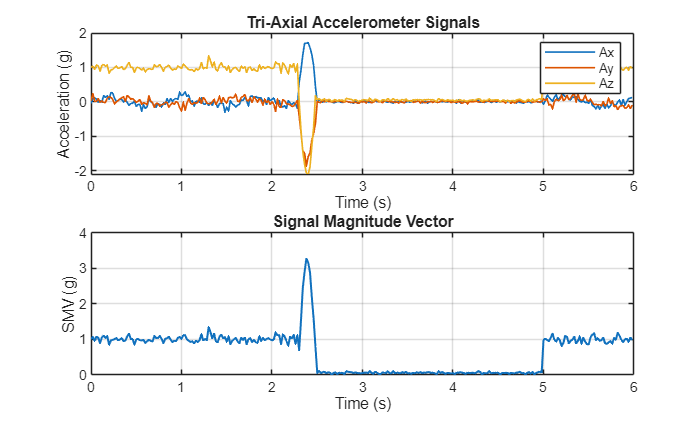


%% I. FIGURE 1: ACCELERATION AND SMV
f1 = figure('Color','w');

subplot(2,1,1);
plot(t,Ax,t,Ay,t,Az,'LineWidth',1);
xlabel('Time (s)');
ylabel('Acceleration (g)');
title('Tri-Axial Accelerometer Signals');
legend('Ax','Ay','Az');
grid on;

subplot(2,1,2);
plot(t,SMV,'LineWidth',1.2);
xlabel('Time (s)');
ylabel('SMV (g)');
title('Signal Magnitude Vector');
grid on;

saveas(f1,fullfile(outdir,'Fig1_Acceleration_SMV.png'));

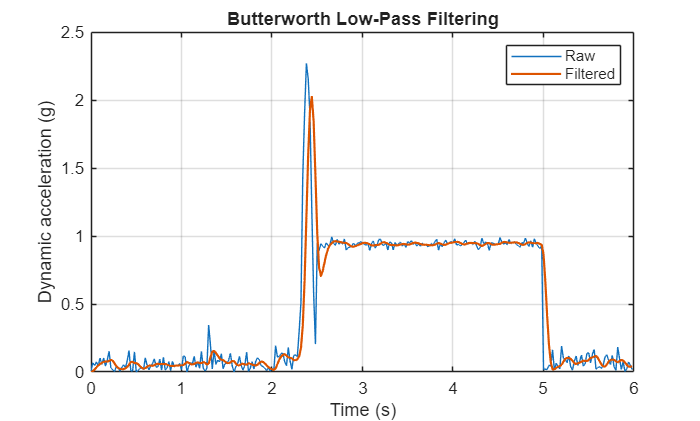


%% J. FIGURE 2: FILTERING
f2 = figure('Color','w');
plot(t,DynamicAccel);
hold on;
plot(t,FilteredAccel,'LineWidth',1.3);
xlabel('Time (s)');
ylabel('Dynamic acceleration (g)');
title('Butterworth Low-Pass Filtering');
legend('Raw','Filtered');
grid on;

saveas(f2,fullfile(outdir,'Fig2_Filtering.png'));

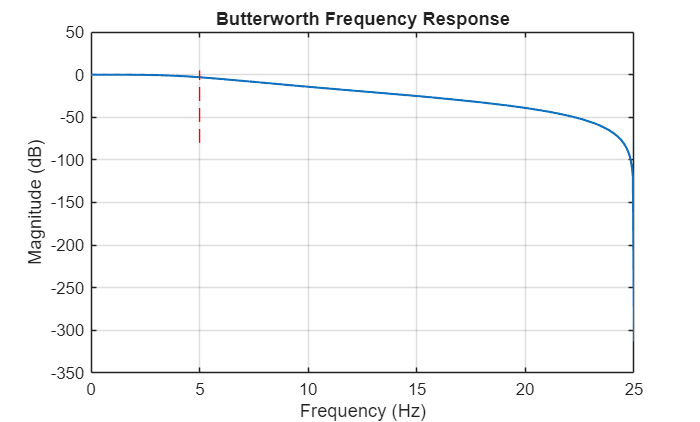


%% K. FIGURE 3: FREQUENCY RESPONSE
freq = linspace(0,Fs/2,500)';
z1 = exp(-1i*2*pi*freq/Fs);

H = (b(1)+b(2)*z1+b(3)*z1.^2) ./ ...
    (a(1)+a(2)*z1+a(3)*z1.^2);

f3 = figure('Color','w');
plot(freq,20*log10(abs(H)+eps),'LineWidth',1.3);
hold on;
plot([fc fc],[-80 5],'--r');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Butterworth Frequency Response');
grid on;

saveas(f3,fullfile(outdir,'Fig3_Filter_Response.png'));

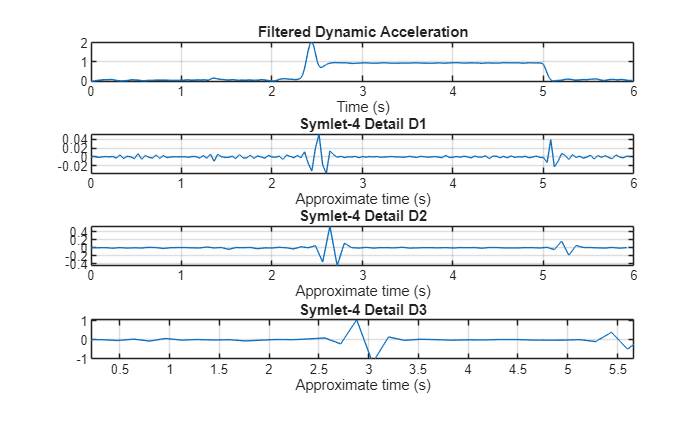


%% L. FIGURE 4: DWT COEFFICIENTS
f4 = figure('Color','w');

subplot(4,1,1);
plot(t,FilteredAccel);
title('Filtered Dynamic Acceleration');
xlabel('Time (s)');
grid on;

subplot(4,1,2);
plot(tD1,D1);
title('Symlet-4 Detail D1');
xlabel('Approximate time (s)');
grid on;

subplot(4,1,3);
plot(tD2,D2);
title('Symlet-4 Detail D2');
xlabel('Approximate time (s)');
grid on;

subplot(4,1,4);
plot(tD3,D3);
title('Symlet-4 Detail D3');
xlabel('Approximate time (s)');
grid on;

saveas(f4,fullfile(outdir,'Fig4_DWT.png'));

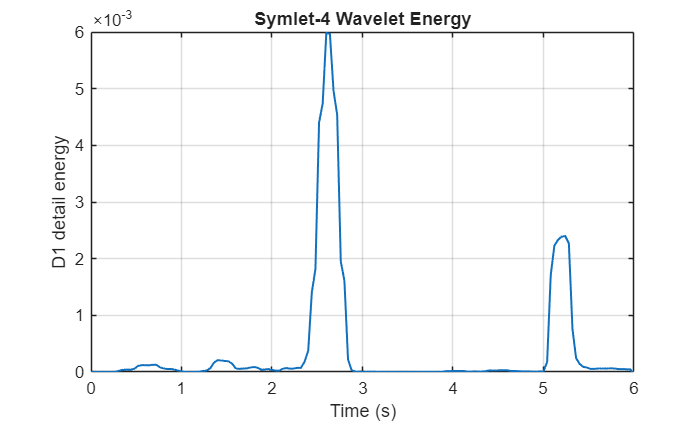


%% M. FIGURE 5: WAVELET ENERGY
f5 = figure('Color','w');
plot(t,ED1,'LineWidth',1.2);
xlabel('Time (s)');
ylabel('D1 detail energy');
title('Symlet-4 Wavelet Energy');
grid on;

saveas(f5,fullfile(outdir,'Fig5_DWT_Energy.png'));

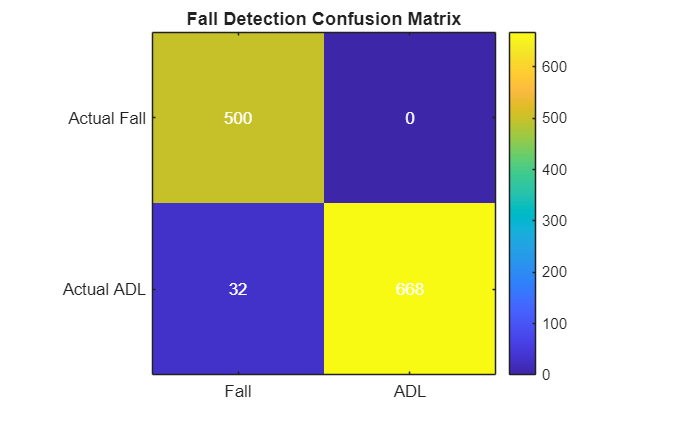


%% N. FIGURE 6: CONFUSION MATRIX
f6 = figure('Color','w');
imagesc([TP FN;FP TN]);
colorbar;
axis equal tight;

set(gca,'XTick',[1 2], ...
    'XTickLabel',{'Fall','ADL'}, ...
    'YTick',[1 2], ...
    'YTickLabel',{'Actual Fall','Actual ADL'});

title('Fall Detection Confusion Matrix');

text(1,1,num2str(TP),'HorizontalAlignment','center','Color','w');
text(2,1,num2str(FN),'HorizontalAlignment','center','Color','w');
text(1,2,num2str(FP),'HorizontalAlignment','center','Color','w');
text(2,2,num2str(TN),'HorizontalAlignment','center','Color','w');

saveas(f6,fullfile(outdir,'Fig6_Confusion_Matrix.png'));

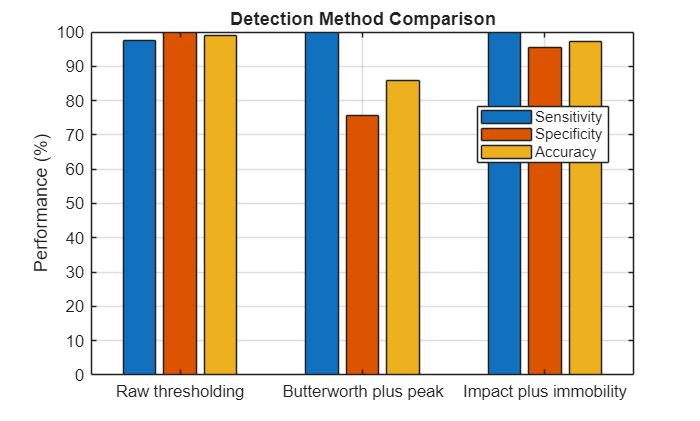


%% O. FIGURE 7: PERFORMANCE COMPARISON
f7 = figure('Color','w');
bar([Sensitivity_pct,Specificity_pct,Accuracy_pct]);
set(gca,'XTick',1:3,'XTickLabel',Method);
ylabel('Performance (%)');
legend('Sensitivity','Specificity','Accuracy','Location','best');
title('Detection Method Comparison');
grid on;

saveas(f7,fullfile(outdir,'Fig7_Method_Comparison.png'));


%% P. EXPORT CSV FILES
fid = fopen(fullfile(outdir,'Performance_Metrics.csv'),'w');
fprintf(fid,'Metric,Value\n');
fprintf(fid,'Sensitivity_pct,%.4f\n',se);
fprintf(fid,'Specificity_pct,%.4f\n',sp);
fprintf(fid,'Accuracy_pct,%.4f\n',acc);
fprintf(fid,'Precision_pct,%.4f\n',prec);
fprintf(fid,'F1_score_pct,%.4f\n',F1);
fclose(fid);

fid = fopen(fullfile(outdir,'Trial_Results.csv'),'w');
fprintf(fid,'Trial,TrueClass,PredictedClass,ExecutionTime_s\n');

for k = 1:num_trials
    fprintf(fid,'%d,%d,%d,%.8f\n',k,trueLabels(k), ...
        predLabels(k),execTime(k));
end

fclose(fid);

fid = fopen(fullfile(outdir,'Method_Comparison.csv'),'w');
fprintf(fid,'Method,Sensitivity_pct,Specificity_pct,Accuracy_pct\n');

for k = 1:3
    fprintf(fid,'%s,%.4f,%.4f,%.4f\n',Method{k}, ...
        Sensitivity_pct(k),Specificity_pct(k),Accuracy_pct(k));
end

fclose(fid);

%% Q. FINAL SUMMARY
fprintf('\n==============================================\n');

fprintf('PROJECT SIMULATION COMPLETED\n');

PROJECT SIMULATION COMPLETED


fprintf('Trials: %d; Falls: %d; ADLs: %d\n', ...
    num_trials,num_falls,num_adls);

Trials: 1200; Falls: 500; ADLs: 700


fprintf('Sensitivity: %.2f%%\n',se);

Sensitivity: 100.00%


fprintf('Specificity: %.2f%%\n',sp);

Specificity: 95.43%


fprintf('Accuracy: %.2f%%\n',acc);

Accuracy: 97.33%


fprintf('Precision: %.2f%%\n',prec);

Precision: 93.98%


fprintf('F1-score: %.2f%%\n',F1);

F1-score: 96.90%


fprintf('Output folder: %s\n',outdir);

Output folder: output_results


fprintf('==============================================\n');


fprintf(['NOTE: Results are from synthetic signals. ' ...
    'They are not clinical validation.\n']);

NOTE: Results are from synthetic signals. They are not clinical validation.



%% LOCAL FUNCTIONS - KEEP ALL FUNCTIONS AT THE END

function [Ax,Ay,Az] = makeSignal(N,Fs,isFall)

t = (0:N-1)'/Fs;
Ax = 0.08*randn(N,1)+0.12*sin(2*pi*1.2*t);
Ay = 0.08*randn(N,1)+0.08*sin(2*pi*0.8*t);
Az = 1+0.08*randn(N,1);

impact = randi([round(1.5*Fs),round(3*Fs)]);
len = round(0.20*Fs);
last = min(N,impact+len-1);
n = (0:last-impact)';

if isFall
    amp = 2.5+1.5*rand();
    pulse = sin(pi*(n+1)/(length(n)+1));

    Ax(impact:last) = Ax(impact:last)+0.6*amp*pulse;
    Ay(impact:last) = Ay(impact:last)-0.5*amp*pulse;
    Az(impact:last) = Az(impact:last)-amp*pulse;

    rs = min(N,last+1);
    re = min(N,rs+round(2.5*Fs)-1);

    Ax(rs:re) = 0.02*randn(re-rs+1,1);
    Ay(rs:re) = 0.02*randn(re-rs+1,1);
    Az(rs:re) = 0.05+0.02*randn(re-rs+1,1);
else
    activity = randi(4);

    switch activity
        case 1
            Ax = Ax+0.25*sin(2*pi*1.5*t);
            Ay = Ay+0.15*sin(2*pi*1.5*t+0.3);

        case 2
            % Standing.

        case 3
            pulse = 0.8*sin(pi*(n+1)/(length(n)+1));
            Az(impact:last) = Az(impact:last)-pulse;

        case 4
            pulse = 1.2*sin(pi*(n+1)/(length(n)+1));
            Az(impact:last) = Az(impact:last)+pulse;
    end
end
end

function y = iirFilter(b,a,x)
x = x(:);
y = zeros(size(x));

for n = 1:length(x)
    for k = 1:length(b)
        ix = n-k+1;
        if ix >= 1
            y(n) = y(n)+b(k)*x(ix);
        end
    end

    for k = 2:length(a)
        ix = n-k+1;
        if ix >= 1
            y(n) = y(n)-a(k)*y(ix);
        end
    end

    y(n) = y(n)/a(1);
end
end

function [D1,D2,D3,A3] = sym4Decompose(x,LoD,HiD)
A = x(:);
D = cell(3,1);

for lev = 1:3
    D{lev} = downFilter(A,HiD);
    A = downFilter(A,LoD);
end

D1 = D{1};
D2 = D{2};
D3 = D{3};
A3 = A;
end

function y = downFilter(x,h)
x = x(:);
y = zeros(ceil(length(x)/2),1);

for n = 1:length(y)
    idx = 2*n-1;

    for k = 1:length(h)
        ix = idx-k+1;
        if ix >= 1 && ix <= length(x)
            y(n) = y(n)+h(k)*x(ix);
        end
    end
end
end

function y = movingEnergy(x,L)
x = x(:);
y = zeros(size(x));

for n = 1:length(x)
    first = max(1,n-L+1);
    y(n) = sum(x(first:n).^2);
end
end

function yq = interpLinear(x,y,xq)
x = x(:);
y = y(:);
xq = xq(:);
yq = zeros(size(xq));

for k = 1:length(xq)
    if xq(k) <= x(1) || xq(k) >= x(end)
        if xq(k) == x(1)
            yq(k) = y(1);
        elseif xq(k) == x(end)
            yq(k) = y(end);
        end
    else
        idx = find(x <= xq(k),1,'last');
        alpha = (xq(k)-x(idx))/(x(idx+1)-x(idx));
        yq(k) = y(idx)+alpha*(y(idx+1)-y(idx));
    end
end
end

function [fall,impactFound,restFound,eventTime] = ...
    detectFall(dyn,Fs,threshold,restThreshold,delayN,postN)

dyn = dyn(:);
fall = false;
impactFound = false;
restFound = false;
eventTime = NaN;

N = length(dyn);
if N <= delayN+postN
    return;
end

candidates = find(dyn > threshold);

for j = 1:length(candidates)
    k = candidates(j);
    restStart = k+delayN;
    restEnd = restStart+postN-1;

    if restEnd > N
        continue;
    end

    impactFound = true;
    post = dyn(restStart:restEnd);

    if var(post,1) < restThreshold
        fall = true;
        restFound = true;
        eventTime = (k-1)/Fs;
        return;
    end
end
end

function [TP,FN,FP,TN,se,sp,acc,prec,F1] = ...
    calculateMetrics(y,p)

y = logical(y(:));
p = logical(p(:));

TP = sum(y & p);
FN = sum(y & ~p);
FP = sum(~y & p);
TN = sum(~y & ~p);

se = 100*TP/max(TP+FN,1);
sp = 100*TN/max(TN+FP,1);
acc = 100*(TP+TN)/max(length(y),1);
prec = 100*TP/max(TP+FP,1);

if prec+se == 0
    F1 = 0;
else
    F1 = 2*prec*se/(prec+se);
end
end

function s = yesno(v)
if v
    s = 'YES';
else
    s = 'NO';
end
end

function s = className(v)
if v
    s = 'FALL';
else
    s = 'ADL';
end
end